A = 0.32345;
B = -0.78743;
C = 0.56532;
sign = 1; %0-unsigned value, 1-signed value % sign
prec_i = 1; %number of integer part bits (Nc) % one bit
prec_f = 8; %number of fractional part bits (Nu) % eight bits
word = 1 + prec_i + prec_f; % whole word

A_fix = fi(A, sign, word, prec_f)

A_fix =     0.3242

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8

B_fix = fi(B, sign, word, prec_f)

B_fix =    -0.7891

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8

C_fix = fi(C, sign, word, prec_f)

C_fix =     0.5664

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8


bin(A_fix)

ans = '0001010011'

bin(B_fix)

ans = '1100110110'

bin(C_fix)

ans = '0010010001'


A_2 = double(A_fix)

A_2 = 0.3242

B_2 = double(B_fix)

B_2 = -0.7891

C_2 = double(C_fix)

C_2 = 0.5664

acc_fix = A_fix + B_fix

acc_fix =    -0.4648

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 8

Y_fix = acc_fix * C_fix

Y_fix =    -0.2633

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 16


acc = A + B

acc = -0.4640

Y = acc * C

Y = -0.2623

error = [];
for i = 0:1:16
    i
    word = 1 + 1 + i;
    A_fix = fi(A, sign, word, i)
    B_fix = fi(B, sign, word, i)
    C_fix = fi(C, sign, word, i)

    acc_fix = A_fix + B_fix
    Y_fix = acc_fix * C_fix
    
    error(i+1) = abs(Y - Y_fix);
end %if

i = 0

A_fix =      0

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 2
        FractionLength: 0

B_fix =     -1

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 2
        FractionLength: 0

C_fix =      1

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 2
        FractionLength: 0

acc_fix =     -1

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 3
        FractionLength: 0

Y_fix =     -1

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 5
        FractionLength: 0

i = 1

A_fix =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 3
        FractionLength: 1

B_fix =     -1

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 3
        FractionLength: 1

C_fix =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 3
        FractionLength: 1

acc_fix =    -0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 4
        FractionLength: 1

Y_fix =    -0.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 2

i = 2

A_fix =     0.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 4
        FractionLength: 2

B_fix =    -0.7500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 4
        FractionLength: 2

C_fix =     0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 4
        FractionLength: 2

acc_fix =    -0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 5
        FractionLength: 2

Y_fix =    -0.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 4

i = 3

A_fix =     0.3750

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 5
        FractionLength: 3

B_fix =    -0.7500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 5
        FractionLength: 3

C_fix =     0.6250

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 5
        FractionLength: 3

acc_fix =    -0.3750

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 6
        FractionLength: 3

Y_fix =    -0.2344

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 6

i = 4

A_fix =     0.3125

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 6
        FractionLength: 4

B_fix =    -0.8125

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 6
        FractionLength: 4

C_fix =     0.5625

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 6
        FractionLength: 4

acc_fix =    -0.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 4

Y_fix =    -0.2812

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 8

i = 5

A_fix =     0.3125

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 5

B_fix =    -0.7812

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 5

C_fix =     0.5625

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 5

acc_fix =    -0.4688

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 8
        FractionLength: 5

Y_fix =    -0.2637

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 15
        FractionLength: 10

i = 6

A_fix =     0.3281

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 8
        FractionLength: 6

B_fix =    -0.7812

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 8
        FractionLength: 6

C_fix =     0.5625

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 8
        FractionLength: 6

acc_fix =    -0.4531

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 6

Y_fix =    -0.2549

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 17
        FractionLength: 12

i = 7

A_fix =     0.3203

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 7

B_fix =    -0.7891

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 7

C_fix =     0.5625

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 7

acc_fix =    -0.4688

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 7

Y_fix =    -0.2637

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 19
        FractionLength: 14

i = 8

A_fix =     0.3242

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8

B_fix =    -0.7891

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8

C_fix =     0.5664

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8

acc_fix =    -0.4648

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 8

Y_fix =    -0.2633

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 16

i = 9

A_fix =     0.3242

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 9

B_fix =    -0.7871

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 9

C_fix =     0.5645

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 9

acc_fix =    -0.4629

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 9

Y_fix =    -0.2613

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 23
        FractionLength: 18

i = 10

A_fix =     0.3232

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 10

B_fix =    -0.7871

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 10

C_fix =     0.5654

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 10

acc_fix =    -0.4639

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 10

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 25
        FractionLength: 20

i = 11

A_fix =     0.3232

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 11

B_fix =    -0.7876

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 11

C_fix =     0.5654

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 11

acc_fix =    -0.4644

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 14
        FractionLength: 11

Y_fix =    -0.2626

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 27
        FractionLength: 22

i = 12

A_fix =     0.3235

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 14
        FractionLength: 12

B_fix =    -0.7874

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 14
        FractionLength: 12

C_fix =     0.5654

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 14
        FractionLength: 12

acc_fix =    -0.4639

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 15
        FractionLength: 12

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 29
        FractionLength: 24

i = 13

A_fix =     0.3235

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 15
        FractionLength: 13

B_fix =    -0.7875

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 15
        FractionLength: 13

C_fix =     0.5653

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 15
        FractionLength: 13

acc_fix =    -0.4640

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 16
        FractionLength: 13

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 31
        FractionLength: 26

i = 14

A_fix =     0.3234

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 16
        FractionLength: 14

B_fix =    -0.7874

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 16
        FractionLength: 14

C_fix =     0.5653

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 16
        FractionLength: 14

acc_fix =    -0.4640

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 17
        FractionLength: 14

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 33
        FractionLength: 28

i = 15

A_fix =     0.3235

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 17
        FractionLength: 15

B_fix =    -0.7874

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 17
        FractionLength: 15

C_fix =     0.5653

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 17
        FractionLength: 15

acc_fix =    -0.4640

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 15

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 35
        FractionLength: 30

i = 16

A_fix =     0.3235

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 16

B_fix =    -0.7874

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 16

C_fix =     0.5653

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 16

acc_fix =    -0.4640

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 19
        FractionLength: 16

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 32

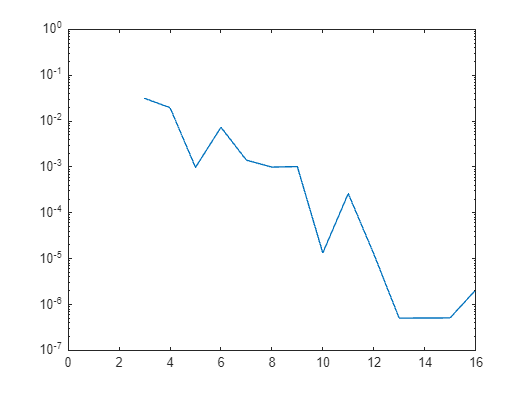

semilogy(0:1:16, error)